# Návrh optimálního regulátoru dle ITAE kritéria

## PI regulátor

- Použity návrhy frekvenčních charakteristik z důvodu nevhodného přechodového děje u Zieglera-Nicholse

- Kp = 1.864e-4, Ti = 0,2680

### Nastavení soustavy

clc
clear
close all
ID  = 256421;
[A, D, g, rho, J, B, ke, R, L, C, Fs, Fv] = gen_sys2025(ID);


Fs =
 
            5.7621e+11
  ------------------------------
  (s+694.2)^2 (s+19.1) (s+3.732)
 
Continuous-time zero/pole/gain model.
Model Properties

Fv =
 
  -1551.4 (s+1190) (s+220.4) (s+0.7153)
  -------------------------------------
     (s+694.2)^2 (s+19.1) (s+3.732)
 
Continuous-time zero/pole/gain model.


### Nastavení poruchy na nulu (před optimalizací)

t = 0:1e-3:3;
iz_data = zeros(size(t));
iz = timeseries(iz_data,t);

### Nastavení řídicí hodnoty

ug_data = 5*ones(size(t));
ug = timeseries(ug_data, t);

## Výpočet ITAE

Kp_teor = 1.864e-4;
Ti_teor = 0.2680;
J_ITAE_PI = ITAE_PI([Kp_teor Ti_teor]);

### Optimalizace pomocí fminsearch, získání optimalizovaného Kp, Ti

x_opt = fminsearch(@ITAE_PI, [Kp_teor Ti_teor]);
Kp = x_opt(1);
Ti = x_opt(2);

###  Spuštění poruchy

t = 0:1e-3:3;
iz_data = 0.02* (t > 0.5);
iz = timeseries(iz_data,t);

## Vykreslení charakteristik

outPI = sim("ITAEmodPI.slx");
figure;
title(tiledlayout(3,2,"TileSpacing","loose"), "Charakteristiky přenosu pro PI regulátor (návrh pomocí ITAE)");

- Objemový průtok (akční zásah)

nexttile;
plot(outPI.Qin.Time, outPI.Qin.Data);
xregion(0.5,0.7,'FaceColor', "r");
Qss = 0.315;
yline(Qss,'--k',sprintf('Q_{in} = %.f ml/s',Qss*1000),'LineWidth',1.3);
grid on;
title('Q_{in} (t)');
xlabel('t [s]');
xlim([0 0.9]);
ylabel('Q_{in} [dm^3\cdot s^{-1}]');

- Výška hladiny

nexttile;
plot(outPI.h.Time, outPI.h.Data);
grid on;
title('h(t)');
xregion(0.5,4,'FaceColor', "y");
xlabel('t [s]');
xlim([0 0.9]);
ylabel('h [cm]');

- Regulační odchylka

nexttile;
plot(outPI.e.Time, outPI.e.Data);
xregion(0.5,0.7,'FaceColor', "r");
xlim([0 0.9]);
grid on;
title('e(t)');
xlabel('t [s]');
ylabel('e [V]');

- Proud tekoucí kotvou DC generátoru

nexttile;
plot(outPI.i.Time, outPI.i.Data);
xlim([0 0.9]);
xregion(0.5,4,'FaceColor', "y");
grid on;
title('i(t)');
xlabel('t [s]');
ylabel('i [mA]');

- Generované napětí generátoru

nexttile;
plot(outPI.ug.Time, outPI.ug.Data);
xregion(0.5,0.7,'FaceColor', "r");
xlim([0 0.9]);
grid on;
title('U_g(t)');
xlabel('t [s]');
ylabel('u_g [V]');

- Úhlová rychlost DC generátoru

nexttile;
plot(outPI.w.Time, outPI.w.Data);
xlim([0 0.9]);
xregion(0.5,4,'FaceColor', "y");
grid on;
title('\omega(t)');
xlabel('t [s]');
ylabel('\omega [rad\cdot s^{-1}]');

### Export naměřených charakteristik do nového .pdf souboru

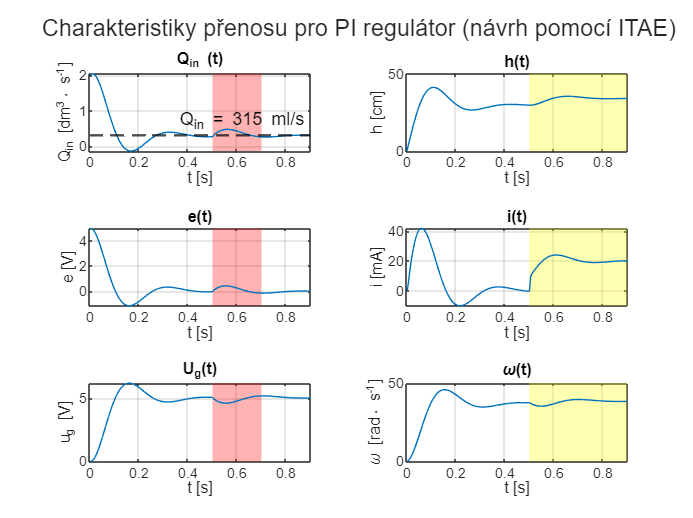

if isfile("ITAEPI.pdf")
    delete("ITAEPI.pdf");
end

exportgraphics(gcf, 'ITAEPI.pdf', 'ContentType', 'vector');

# Návrh PID regulátoru

## PID regulátor s realizační konstantou N = 10

- Výpočet ITAE

Kp_teor = 0.0015;
Ti_teor = 0.3163;
Td_teor = 0.0403;
N = 10;
J_ITAE_PID = ITAE_PID([Kp_teor Ti_teor Td_teor]);


- Spuštění vlastní optimalizace

x_opt = fminsearch(@ITAE_PID, [Kp_teor Ti_teor Td_teor]);

Error using ITAE_PID (line 7)
Simulation aborted

Error in fminsearch (line 336)
    fxr = funfcn(x,varargin{:});

## Načtení parametrů

Kp = x_opt(1)
Ti = x_opt(2)
Td = x_opt(3)

## Spuštění poruchy po ustálení

t = 0:1e-3:3;
iz_data = 0.02 * (t > 0.4);
iz = timeseries(iz_data, t);

## Vykreslení charakteristik

outPID = sim("ITAEmodPID.slx");

figure;
title(tiledlayout(3,2,"TileSpacing","loose"), "Charakteristiky přenosu pro PID regulátor s N = 10 (návrh pomocí ITAE)");

- Objemový průtok (akční zásah)

nexttile;
plot(outPID.Qin.Time, outPID.Qin.Data);
grid on;
title('Q_{in} (t)');
xlabel('t [s]');
xlim([0 0.9]);
ylabel('Q_{in} [dm^3\cdot s^{-1}]');

- Výška hladiny

nexttile;
plot(outPID.h.Time, outPID.h.Data);
yline(35,'--k',sprintf('h = %.f ml/s, \\Delta h = %.f',35, 35-30),'LineWidth',1.3);
grid on;
title('h(t)');
xlabel('t [s]');
xlim([0 0.7]);
ylabel('h [cm]');

- Regulační odchylka

nexttile;
plot(outPID.e.Time, outPID.e.Data);
xlim([0 0.9]);
grid on;
title('e(t)');
xlabel('t [s]');
ylabel('e [V]');

- Proud tekoucí kotvou DC generátoru

nexttile;
plot(outPID.i.Time, outPID.i.Data);
xlim([0 0.7]);
grid on;
title('i(t)');
xlabel('t [s]');
ylabel('i [mA]');

- Generované napětí generátoru

nexttile;
plot(outPID.ug.Time, outPID.ug.Data);
xlim([0 0.7]);
grid on;
title('U_g(t)');
xlabel('t [s]');
ylabel('u_g [V]');

- Úhlová rychlost DC generátoru

nexttile;
plot(outPID.w.Time, outPID.w.Data);
xlim([0 0.6]);
grid on;
title('\omega(t)');
xlabel('t [s]');
ylabel('\omega [rad\cdot s^{-1}]');
    

### Export naměřených charakteristik do nového .pdf souboru

if isfile("ITAEPID10.pdf")
    delete("ITAEPID10.pdf");
end
exportgraphics(gcf, 'ITAEPID10.pdf', 'ContentType', 'vector');

## PID regulátor s realizační konstantou N = 100

N = 100;
Kp_teor = 0.0032;
Ti_teor = 0.3199;
Td_teor = 0.0434;
J_ITAE_PID = ITAE_PID([Kp_teor Ti_teor Td_teor]);

### Nastavení poruchy na nulu (před optimalizací)

t = 0:1e-3:3;
iz_data = zeros(size(t));
iz = timeseries(iz_data,t);

- Spuštění vlastní optimalizace

x_opt = fminsearch(@ITAE_PID, [Kp_teor Ti_teor Td_teor]);

## Načtení parametrů

Kp = x_opt(1)
Ti = x_opt(2)
Td = x_opt(3)

## Spuštění poruchy po ustálení

t = 0:1e-3:3;
iz_data = 0.02 * (t > 0.4);
iz = timeseries(iz_data, t);

## Vlastní vykreslení charakteristik

outPID = sim("ITAEmodPID.slx");
figure;
title(tiledlayout(3,2,"TileSpacing","loose"), "Charakteristiky přenosu pro PID regulátor s N = 100 (návrh pomocí ITAE)");

- Objemový průtok (akční zásah)

nexttile;
plot(outPID.Qin.Time, outPID.Qin.Data);
grid on;
title('Q_{in} (t)');
xlabel('t [s]');
xlim([0 0.9]);
ylabel('Q_{in} [dm^3\cdot s^{-1}]');

- Výška hladiny

nexttile;
plot(outPID.h.Time, outPID.h.Data);
grid on;
title('h(t)');
xlabel('t [s]');
xlim([0 0.9]);
ylabel('h [cm]');

- Regulační odchylka

nexttile;
plot(outPID.e.Time, outPID.e.Data);
xlim([0 0.9]);
grid on;
title('e(t)');
xlabel('t [s]');
ylabel('e [V]');

- Proud tekoucí kotvou DC generátoru

nexttile;
plot(outPID.i.Time, outPID.i.Data);
xlim([0 0.9]);
grid on;
title('i(t)');
xlabel('t [s]');
ylabel('i [mA]');

- Generované napětí generátoru

nexttile;
plot(outPID.ug.Time, outPID.ug.Data);
xlim([0 0.9]);
grid on;
title('U_g(t)');
xlabel('t [s]');
ylabel('u_g [V]');

- Úhlová rychlost DC generátoru

nexttile;
plot(outPID.w.Time, outPID.w.Data);
xlim([0 0.9]);
grid on;
title('\omega(t)');
xlabel('t [s]');
ylabel('\omega [rad\cdot s^{-1}]');

### Export naměřených charakteristik do nového .pdf souboru

if isfile("ITAEPID100.pdf")
    delete("ITAEPID100.pdf");
end
exportgraphics(gcf, 'ITAEPID100.pdf', 'ContentType', 'vector');